**Student Name:** Naman Shah

**Last 4 Digits of RUID:** 8939

**Section:** C1

**Math 250 MATALB Assignment:** 5

rand('seed', 8939)

**Question 1**. Graphic Demonstration of Eigenvectors and Eigenvalues

(1)(a)

eigshow

(1)(a)(j)

A has one positive eigenvalue

(1)(a)(ii)

A has one negative eigenvalue

(1)(a)(iii)

Assuming x is of unit length, we see Ax is approximately 3/2 times x height, making the eigenvalue 1.5 and the negative value to be 0.5 as the Ax is 1/2 for the same.

(1)(b)

eigshow

(1)(b)(i)

There are no lines that contain both Ax and x for this one.

(1)(b)(ii)

No, but it might have imaginary eigenvalues.

**Question 2**. Characteristic Polynomial

(2)(a)

A = [1 3; 4 2]/4

A =     0.2500    0.7500
    1.0000    0.5000


syms t
I = eye(2)

I =      1     0
     0     1


p = det(A - t*I)

$$p = t^{2}-\frac{3\,t}{4}-\frac{5}{8}$$

Yes, this is the same polynomial.

(2)(b)

solve(p)

$$ans = \left(\begin{array}{c} -\frac{1}{2}\\ \frac{5}{4} \end{array}\right)$$

Yes, this answer is correct.

(2)(c)

A = [3 1; -2 4]

A =      3     1
    -2     4


syms t
I = eye(2)

I =      1     0
     0     1


p = det(A - t*I)

$$p = t^{2}-7\,t+14$$

solve(p)

$$ans = \left(\begin{array}{c} \frac{7}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2}\\ \frac{7}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

No, the eigenvalues of A are not real, they are imaginary numbers.

This explains the fact that we could not find a single x that was parralel to Ax in question 1, as there were no real eigenvalues for the matrix to begin with.

**Question 3**. Eigenvectors and Diagonalization

A = rmat(3,3)

A =      8     6     6
     2     5     9
     1     8     7


A =      8     6     6
     2     5     9
     1     8     7


z = eig(A) - real(eig(A))

z =      0
     0
     0


syms t
I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1


p = det(A - t*I)

$$p = -t^{3}+20\,t^{2}-41\,t-260$$

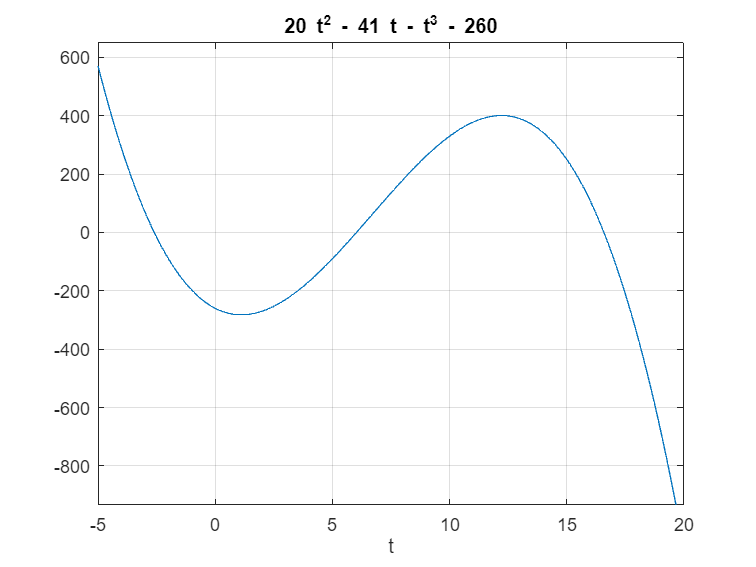

figure
ezplot(p, [-5, 20])
grid

Approximate values for p(t): t =  -2.6, 6.1, 16.4

(3)(b)

[P D] = eig(A)

P =     0.7031    0.9696    0.0773
    0.5081   -0.0936   -0.7700
    0.4976   -0.2261    0.6334


D =    16.5818         0         0
         0    6.0220         0
         0         0   -2.6038


p1 = P(:,1)

p1 =     0.7031
    0.5081
    0.4976


p2 = P(:,2)

p2 =     0.9696
   -0.0936
   -0.2261


p3 = P(:,3)

p3 =     0.0773
   -0.7700
    0.6334


A*p1 - D(1,1)*p1

ans = 1.0e-14 *

   -0.8882
         0
         0


A*p2 - D(2,2)*p2

ans = 1.0e-14 *

   -0.7105
   -0.2442
   -0.1776


A*p3 - D(3,3)*p3

ans = 1.0e-14 *

   -0.1721
    0.0888
         0


Theorem 5.2 let's us know that a n x n matrix is diagonalizable if and only if there is a basis for R^n consisting of eigenvectors of A. Thus, A = P*D*P^-1, where D is a diagonal matrix and P is an invertible matrix, if and only if the columns of P are a basis for R^n consisting of eigenvectors of A and the diagonal entries of D are the eigenvalues corresponding to the respective columns of P. 

Furthermore, this calculation tells us that since each column of P is an eigenvector of A and each diagonal entry of D is the corresponding eigenvalue, that the columns of P are the basis for R^n consisting of eigenvectors of A.

(3)(c)

A

A =      8     6     6
     2     5     9
     1     8     7


P*D*inv(P)

ans =     8.0000    6.0000    6.0000
    2.0000    5.0000    9.0000
    1.0000    8.0000    7.0000


Yes, A = PDP^-1

A^5

ans =       247508      649086      758886
      173662      471965      552729
      169181      462848      541927


P*D^5*inv(P)

ans = 1.0e+05 *

    2.4751    6.4909    7.5889
    1.7366    4.7196    5.5273
    1.6918    4.6285    5.4193


A^10

ans = 1.0e+11 *

    3.0237    8.1825    9.5786
    2.1846    5.9130    6.9220
    2.1394    5.7909    6.7790


P*D^10*inv(P)

ans = 1.0e+11 *

    3.0237    8.1825    9.5786
    2.1846    5.9130    6.9220
    2.1394    5.7909    6.7790


The values are very very close, meaning A^5 =  P D^5 P^-1 and A^10 = P D^10 P^-1.

**Question 4**. Steady-State Eigenvector for a Transition Matrix

(4)(a)

A = eye(2)

A =      1     0
     0     1


B = rand(2)

B =     0.6041    0.4857
    0.6322    0.4651


A(:,1) = B(:,1)/sum(B(:,1))

A =     0.4886         0
    0.5114    1.0000


A(:,2) = B(:,2)/sum(B(:,2))

A =     0.4886    0.5108
    0.5114    0.4892


A

A =     0.4886    0.5108
    0.5114    0.4892


[1 1]*A

ans =      1     1


When writing out the calculation by hand, I observed that [1 1]*A fills out to be [(A(1,1) + A(2,1)) (A(2,1)+A*2,2)], meaning that each value in the resulting matrix of [1 1]*A is the sum of the corresponding entries in each column of A. Therefore, by definition, because these sums equal 1, we have shown that A is a transition matrix.

(4)(b)

u = nulbasis(A - eye(2))

u =     0.9989
    1.0000


v = u/sum(u)

v =     0.4997
    0.5003


Yes both components of v add up to be one.

A*v

ans =     0.4997
    0.5003


v

v =     0.4997
    0.5003


Yes, A*v = v.

Thus, v is an eigenvector for A with eigenvalue A, called the steady-state vector for A.

figure
plot([0, v(1)], [0, v(2)]), hold on

(4)(c)

w =  rand(2, 1)

w =     0.7318
    0.0639


p = w/sum(w)

p =     0.9197
    0.0803


p = A*p, plot([0, p(1)], [0, p(2)], ':'), hold on

p =     0.4904
    0.5096


p = A*p, plot([0, p(1)], [0, p(2)], ':'), hold on

p =     0.4999
    0.5001


p = A*p, plot([0, p(1)], [0, p(2)], ':'), hold on

p =     0.4997
    0.5003


p = A*p, plot([0, p(1)], [0, p(2)], ':'), hold on

p =     0.4997
    0.5003


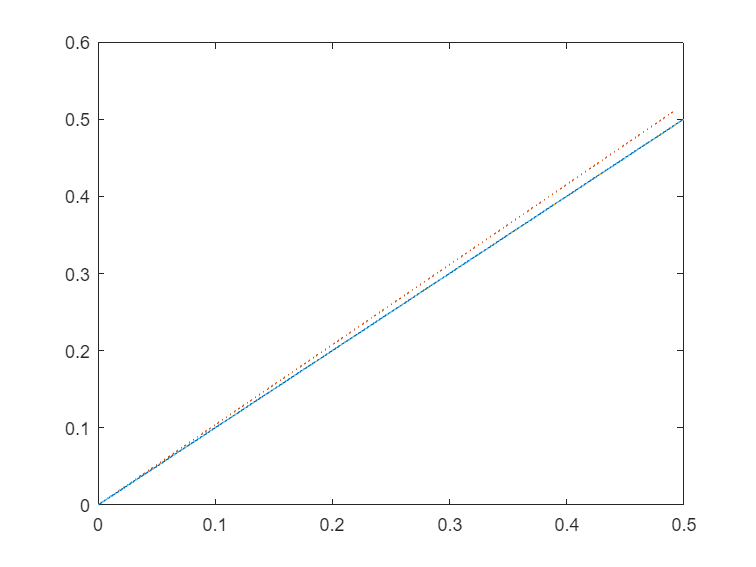

p =     0.4997
    0.5003


p = A*p, plot([0, p(1)], [0, p(2)], ':'), hold on

Now, we closely resemble the vector.

**Question 5**. Markov Chains

(5)(a)

A = [0.6, 0.1, 0.5; 0.2, 0.7, 0.1; 0.2, 0.2, 0.4]

A =     0.6000    0.1000    0.5000
    0.2000    0.7000    0.1000
    0.2000    0.2000    0.4000


u = [1, 1, 1]

u =      1     1     1


u*A

ans =     1.0000    1.0000    1.0000


Yes, u*A = u.

(5)(b)

p = [0.5; 0.3; 0.2]

p =     0.5000
    0.3000
    0.2000


u*p

ans = 1

Yes u*p = 1.

Years: 1, 2, 3, 5, and 8 years.

After one year:

A*p

ans =     0.4300
    0.3300
    0.2400


City: 43%, Suburb: 33%, Country: 24%

After two years:

(A^2)*p

ans =     0.4110
    0.3410
    0.2480


City: 41.1%, Suburb: 34.1%, Country: 24.8%

After three years:

(A^3)*p

ans =     0.4047
    0.3457
    0.2496


City: 40.47%, Suburb: 34.57%, Country: 24.96%

After five years:

(A^5)*p

ans =     0.4011
    0.3490
    0.2500


City: 40.11%, Suburb: 34.9%, Country: 25%

After eight years:

(A^8)*p

ans =     0.4001
    0.3499
    0.2500


City: 40.01%, Suburb: 34.99%, Country: 25%

(5)(c)

u = nulbasis(A - eye(3))

u =     1.6000
    1.4000
    1.0000


v = u/sum(u)

v =     0.4000
    0.3500
    0.2500


The vector v, and the population distribution are nearly identical by a margin of 0.01, showing that after 8 years, the population will be similar. 